%Loading Dataset from extracted folder on our local machine
dataset_path = 'C:\Users\Hazem Abdelaziz\Downloads\GP-Github\Autonomous-Vehicle-Localization-Using-Onboars-Sensor-and-HD-Geolocated-Maps-Project-Solution\KITTI\City_2011_09_26_drive_0009\2011_09_26\2011_09_26_drive_0009_sync';
%Setting number of frames 
freamesNum = 447;

%Store stereo camera first frame (For center cameras 0: Gray & 2: RGB)
gray_image = imread(fullfile(dataset_path, 'image_00\data', '0000000000.png'));
rgb_image = imread(fullfile(dataset_path, 'image_02\data', '0000000000.png'));

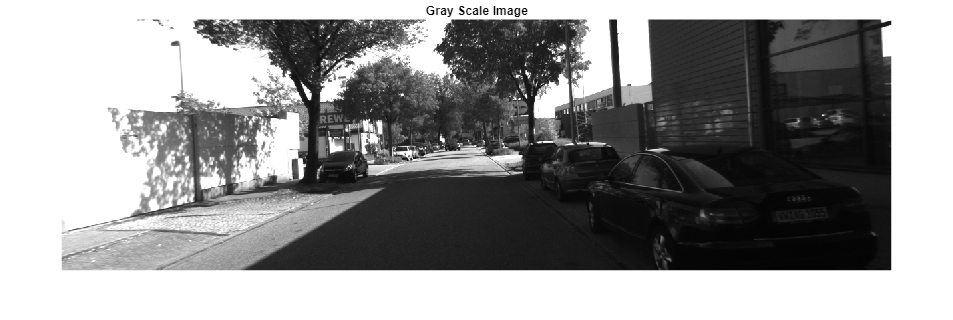

% Display the images
figure;
imshow(gray_image);
title('Gray Scale Image');

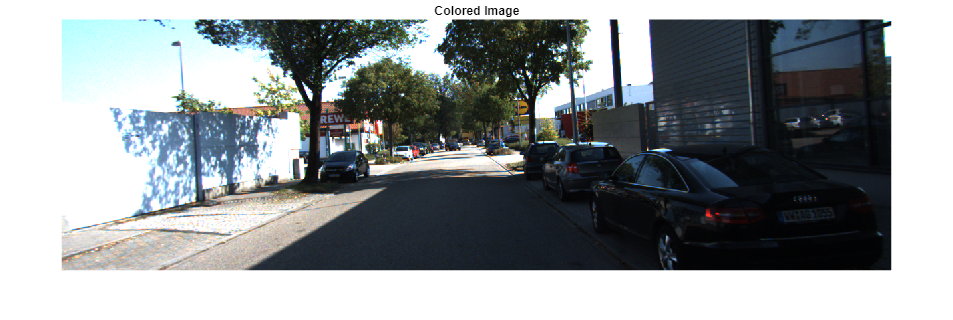

figure;
imshow(rgb_image);
title('Colored Image');

%Store Colored image in a image vector
rgbFolderPath = strcat(dataset_path, '\image_02\data');
pngFiles = dir(fullfile(rgbFolderPath, '*.png'));
rgbVector = cell(1, numel(pngFiles));
for i = 1:numel(pngFiles)
    %Construct the full file path
    filePath = fullfile(rgbFolderPath, pngFiles(i).name);
    %Read the image and store it
    rgbVector{i} = imread(filePath);
end

%This Cell is to save a video consisting of multiple images in a vector
%Each image of type cell
%{
outputVideo = VideoWriter('output_video.avi'); 
outputVideo.FrameRate = 10; %Frame rate that the images vector recorded at for a better display
open(outputVideo);

for i = 1:numel(rgbVector)
    % Convert image from cell to matrix
    frame =rgbVector{i};
    
    %write the frame to the video
    writeVideo(outputVideo, frame);
end

% Close the video file
close(outputVideo);
%}

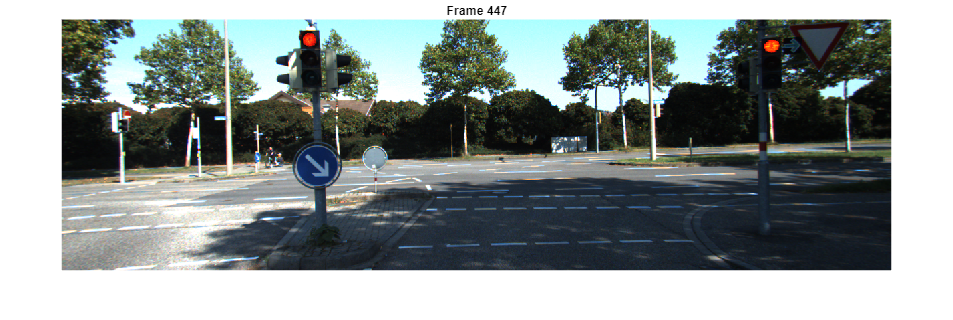

%This cell is to display the sequence of rgb colored image frames
for i = 1:numel(rgbVector)
    % Display the current image
    imshow(rgbVector{i});
    title(['Frame ', num2str(i)]); %Adding frame number as a title
    pause(0.1); %Pausing the video according to recorded frame rate 
end

pcdFolderPath = strcat(dataset_path, '\velodyne_points\data');
pcdFiles = dir(pcdFolderPath);
%This section is to convert from bin file data to 
% !! This section is to be run once to avoid overwriting and saving files
%multiple times, to convert it for the fisrt time uncomment the section
%bellow
%{
for i = 1:length(pcdFiles)
    cd(pcdFolderPath);
    filename = pcdFiles(i).name;
    if(length(filename) > 10)
        binOpen = fopen(filename, 'rb'); %Open binary in read mode
        binData = fread(binOpen, [4, inf], 'single')'; %Reading data from binary file
        fclose(binOpen);
        extension_to_remove = '.bin';
        original_str = filename;
        start_idx = strfind(original_str, extension_to_remove);
        end_idx = start_idx + length(extension_to_remove) - 1;
        modified_str = original_str;
        modified_str(start_idx:end_idx) = ''; 
        save(strcat(modified_str,'.mat'), 'binData');
    end
end
%}

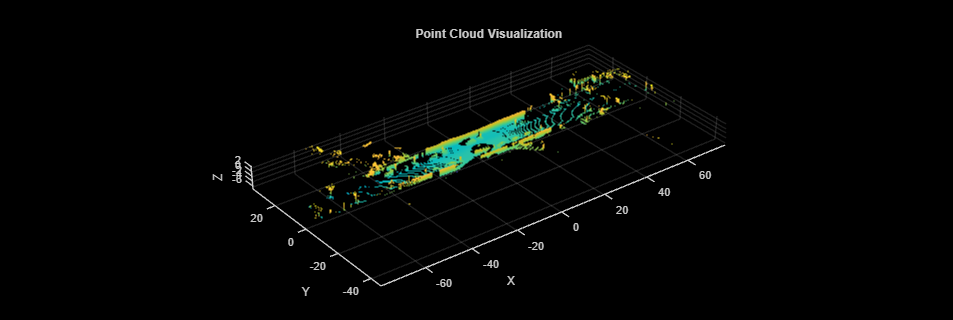

%visualize a LiDAR point cloud from a frame
point_cloud = load(fullfile(pcdFolderPath, '0000000000.mat'));
pcdX = point_cloud.binData(:,1);
pcdY = point_cloud.binData(:,2);
pcdZ = point_cloud.binData(:,3);
point_cloud_data = [pcdX, pcdY, pcdZ];
pcshow(point_cloud_data)
xlabel('X');
ylabel('Y');
zlabel('Z');
title('Point Cloud Visualization');

pcdMat = NaN(117630, 3, freamesNum); %This matrix will hold our point cloud
matFiles = dir(fullfile(pcdFolderPath, '*.mat'));
for i = 1:numel(matFiles)
    point_cloud = load(fullfile(pcdFolderPath, matFiles(i).name));
    pcdMat(1:size(point_cloud.binData(:,1)),1,i) = point_cloud.binData(:,1);
    pcdMat(1:size(point_cloud.binData(:,2)),2,i) = point_cloud.binData(:,2);
    pcdMat(1:size(point_cloud.binData(:,3)),3,i) = point_cloud.binData(:,3);
end

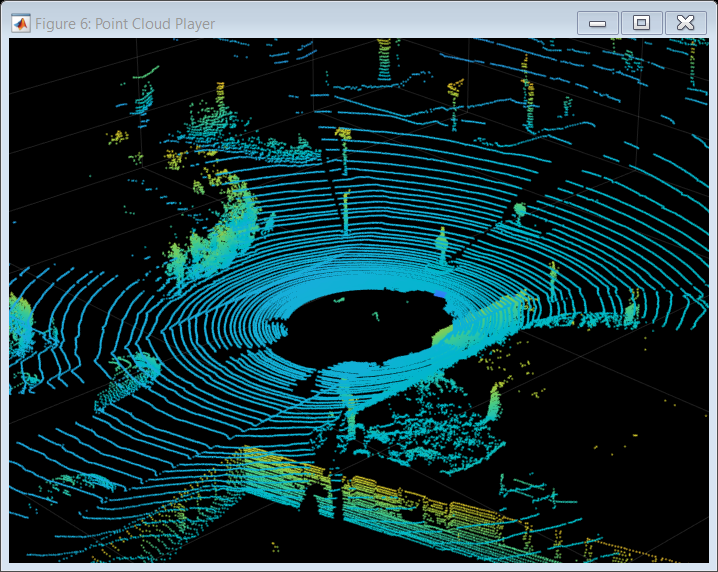

xlimits = [-70 70];
ylimits = [-70 70];
zlimits = [ -25 25];
coder.extrinsic('isOpen', 'pcplayer')
player = pcplayer(xlimits, ylimits, zlimits);
for i = 1:numel(matFiles)
    pcdX = pcdMat(:,1,i);
    pcdY = pcdMat(:,2,i);
    pcdZ = pcdMat(:,3,i);
    point_cloud_data = [pcdX, pcdY, pcdZ];
    % Update the plot with the point cloud for the current frame
    view(player, point_cloud_data);
    pause(0.1); % Adjust the pause duration as needed
end

%Reading GPS/IMU data from OXTS folder
%Data are stored in the format show at dataformat.txt file
oxtsFolderPath = strcat(dataset_path, '\oxts\data');
oxtsFiles = dir(oxtsFolderPath);
cd(oxtsFolderPath);
OXTS = zeros(freamesNum,30);
j = 1;
for i = 3:length(oxtsFiles)
    filename = oxtsFiles(i).name;
    if(length(filename) > 5)
        OXTS(j,:) = importdata(filename);
    end
    j = j +1;
end

%Seperating OXTS folder to Data vectors needed for further processing
latitude = OXTS(:,1);
longitude = OXTS(:,2);
altitude = OXTS(:,3);
roll = OXTS(:,4);
pitch = OXTS(:,5);
yaw = OXTS(:,6);
vf = OXTS(:,9);
vl = OXTS(:,10);
vu = OXTS(:,11);
ax = OXTS(:,12);
ay = OXTS(:,13);
az = OXTS(:,14);
wx = OXTS(:,18);
wy = OXTS(:,19);
wz = OXTS(:,20);

%Creating time frame starting from Second 0 
timeVector = 0:0.1:(freamesNum-1)*0.1;

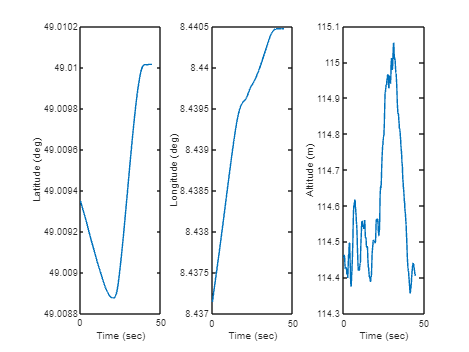

%Creating subplots to visualize GPS geodatic frame data
figure;
set(gcf, 'Color', 'white');

subplot(1,3,1);
plot(timeVector, latitude);
xlabel('Time (sec)');
ylabel('Latitude (deg)');

subplot(1,3,2);
plot(timeVector, longitude);
xlabel('Time (sec)');
ylabel('Longitude (deg)');

subplot(1,3,3);
plot(timeVector, altitude);
xlabel('Time (sec)');
ylabel('Altitude (m)');